# Effect Size and Power

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Effect Size and Power')

## Cohen's D: 1 Sample

data1 = [13,14,15,17,18,19,21,20,19,20];
X = mean(data1);
s = std(data1);
mu = 15;
d = (X - mu) / s;
abs(d) % report positive value

ans = 0.9431

## Cohen's D: 2 sample

group1 = normrnd(300.4, 34.9, [300 1]);
group2 = normrnd(306.7, 30.1, [350 1]);
d2 = (mean(group1) - mean(group2)) / (sqrt((((length(group1) - 1) * varDDOF(group1, 1)) + ((length(group2) - 1) * varDDOF(group2, 2))) / (length(group1) + length(group2) - 2)));

abs(d2)

ans = 0.1471

## Cohen's D: Paired Samples

data2a = [22,25,17,24,16,29,20,23,19,20];
data2b = [18,21,16,22,19,24,17,21,23,18];
data2diff = data2a - data2b;
d2 = (mean(data2diff) - 0) / (sqrt(std(data2a)^2 + std(data2b)^2- 2 * corr(data2a',data2b') * std(data2a) * std(data2b))/ sqrt(2*(1-corr(data2a',data2b'))))

d2 = 0.4475

## Common Language Effect Size - 2 sample

a = [1, 3, 5];
b = [2, 4, 6];
c = nan(length(a), length(b)); 
for i = 1:length(a)
    for j = 1:length(b)
        if a(i) > b(j) 
            c(i,j) = 1;
        elseif a(i) == b(j) 
            c(i,j) = 0.5;
        else 
            c(i,j) = 0.0;
        end 
    end 
end 
CLES = (abs(sum(c,'all') / (length(a) * length(b)) - 0.5) + 0.5) * 100

CLES = 66.6667


a = group1;
b = group2;
c = nan(length(a), length(b)); 
for i = 1:length(a)
    for j = 1:length(b)
        if a(i) > b(j) 
            c(i,j) = 1;
        elseif a(i) == b(j) 
            c(i,j) = 0.5;
        else 
            c(i,j) = 0.0;
        end 
    end 
end 
CLES = (abs(sum(c,'all') / (length(a) * length(b)) - 0.5) + 0.5) * 100

CLES = 54.6267

## Common Language Effect Size - 1 Sample

a = data1; % data
b = zeros(size(a))+15; % mean value you are comparing to (i.e., mu_0 = 15)
c = nan(length(a),length(b));
for i = 1:length(a)
    for j = 1:length(b)
        if a(i) > b(j)
            c(i,j) = 1;
        elseif a(i) == b(j)
            c(i,j) = 0.5;
        else
            c(i,j) = 0.0;
        end
    end
end
CLES = (abs(sum(c,'all') / (length(a) * length(b)) - 0.5) + 0.5) * 100

CLES = 75

## Common Language Effect Size - Paired

a1 = data2a;
a2 = data2b;
a = a2 - a1; 
b = zeros(size(a)); 
c = nan(length(a),length(b));
for i = 1:length(a)
    for j = 1:length(b)
        if a(i) > b(j)
            c(i,j) = 1;
        elseif a(i) == b(j)
            c(i,j) = 0.5;
        else
            c(i,j) = 0.0;
        end
    end
end
CLES = (abs(sum(c,'all') / (length(a) * length(b)) - 0.5) + 0.5) * 100

CLES = 80

## Power Analysis (a priori) Cont'd

d2 = (300.4 - 306.7) / (sqrt((((300 - 1) * 34.9^2) + ((350 - 1) * 30.1^2)) / (300 + 350 - 2)))

d2 = -0.1944

d2abs = abs(d2)

d2abs = 0.1944

% TODO - recommend doing in Python or R

## Numerical Power Analysis (a priori) Cont'd

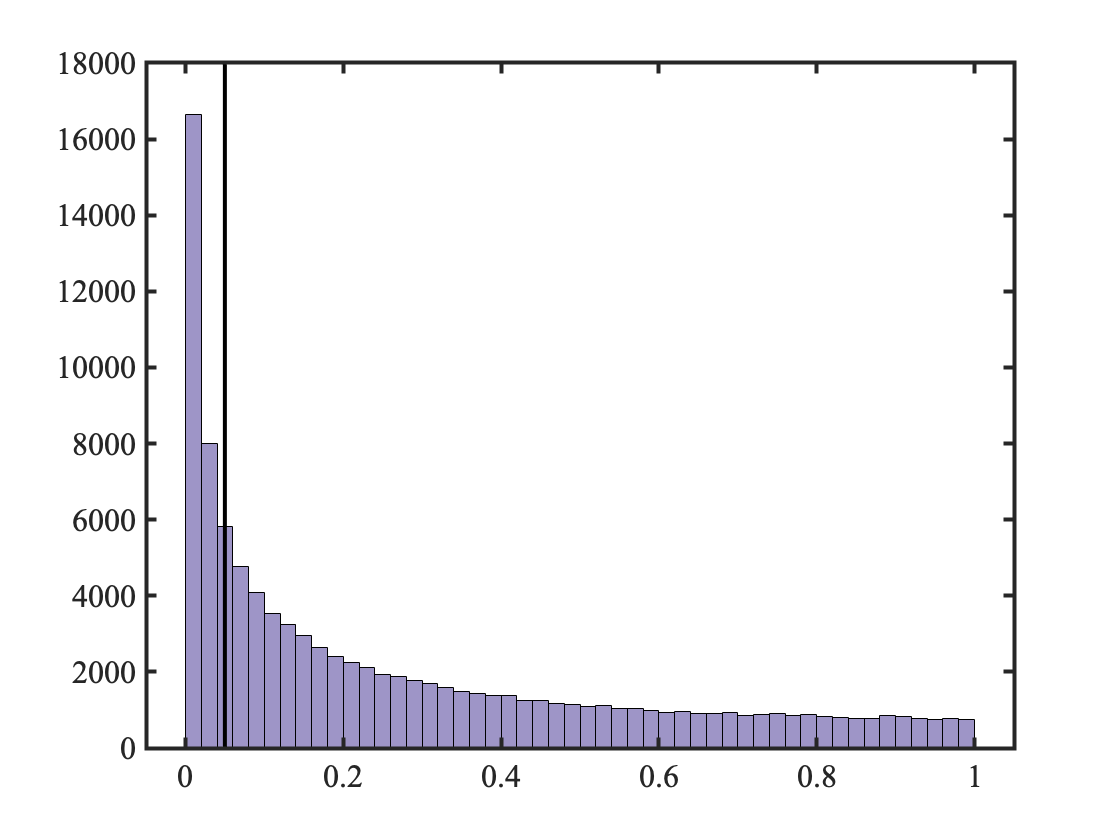

PVALUES1 = nan([100000 1]);
n = 100;
for i = 1:100000
    group1 = normrnd(300.4, 34.9, [n 1]);
    group2 = normrnd(306.7, 30.1, [n 1]);
    [~, PVALUES1(i)] = ttest2(group1, group2);
end
figure();
histogram(PVALUES1); 
hold on;
plot([0.05 0.05], get(gca, 'ylim'), 'k-')

sum(PVALUES1 < 0.05) / 100000 * 100

ans = 27.7100

auto_save('NPA_sim')

## Numerical Power Analysis Cont'd (a priori) - Power Curve 

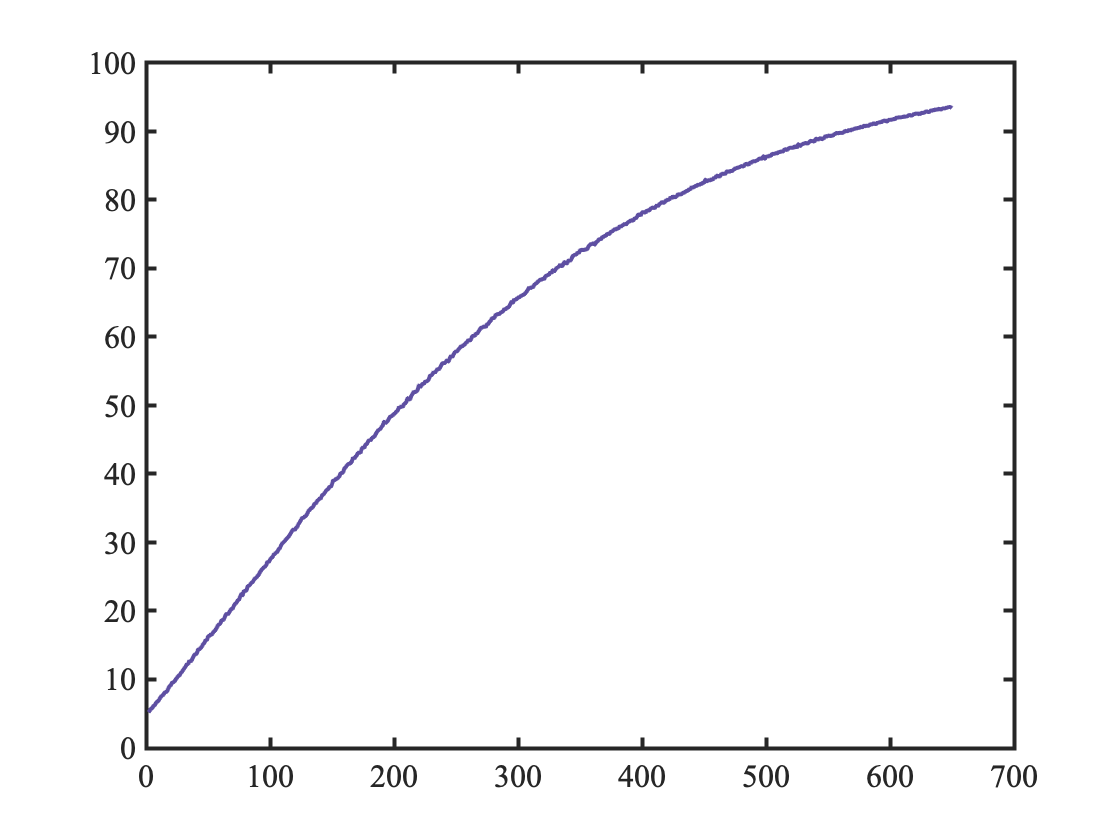

min_n = 2;
max_n = 650;
POWER1 = nan(max_n - min_n, 1);
for n = min_n:max_n
    PVALUES1 = nan([100000 1]);
    for i = 1:100000
        group1 = normrnd(300.4, 34.9, [n 1]);
        group2 = normrnd(306.7, 30.1, [n 1]);
        [~, PVALUES1(i)] = ttest2(group1, group2);
    end
    POWER1(n) = sum(PVALUES1 < 0.05) / 100000 * 100;
end

figure();
plot(POWER1)

auto_save('NPA_curve')

## Local functions

function v = varDDOF(data, ddof)
arguments 
    data (:,1);
    ddof (1,1) = 1; 
end
v = (1 / (length(data) - ddof)) * sum(abs(data - mean(data)).^2);
end

function ttest2Power(d, N, power, alpha)
arguments
    d (1,1);
    N (1,1) = 1; 
    power (1,1) = 0.80;
    alpha (1,1) = 0.05;
end
% Calculate t_critical for desired alpha
tcrit = tinv( (1-alpha/2) , (N-1) );
% Calculate d_critical
dcrit = tcrit./sqrt(N);
% Standardize d
dstand = (d-dcrit)./(1./sqrt(N));
% Calculate power as probability of dstand
dpower = tcdf(dstand,(N-1));
% nreq = max(find(((power-.01)<dpower)&(dpower<(power+.01))));
end
